## User Params

Np = 1;      % CT primary turns
Ns = 100;    % CT secondary turns
Ip_max = 300;    % Max primary current, A
Vcc = 3.3;  % Positive Supply voltage, V
Vee = 0;    % Negative supply voltage, V
PRF_max_duty_cycle = 10;    % Max PRF duty cycle (%)

% Current Sense Parameters 
% Max output swing of TLV9062
Vout_min = Vee + 0.04;
Vout_max = Vcc - 0.04;
Vshunt_max = 100e-3; % Max shunt voltage for TLV9062 diff input, V


Is_max = Ip_max*(Np/Ns);        % Max secondary current, A
Is_min = -Is_max;

Rs_max = Vshunt_max/Is_max; % Max shunt resistance, Ohms

Gain = (Vout_max - Vout_min)/(Rs_max*(Is_max-Is_min));

% Gain is R4/R3
R3 = 1.3e3;
R4 = Gain*R3;    % ~21k

% Current Sense Shunt Resistor Power Dissapation @ max duty cycle
R_sense_shunt = Rs_max;   % Current Sense Shunt Resistor, Ohm
Pdis_sense_max = (((Is_max*R_sense_shunt)^2)/R_sense_shunt)*PRF_max_duty_cycle/100;


% OCD Burden Resistor Power Dissapation @ max duty cycle
R_ocd_burden = 1;   % OCD Burden Resistor, Ohm
Pdis_OCD_max = (((Is_max*R_ocd_burden)^2)/R_ocd_burden)*PRF_max_duty_cycle/100;


% ZCD Burden Resistor Power Dissapation @ max duty cycle
R_zcd_burden = 0.5;   % ZCD Burden Resistor, Ohm
Pdis_ZCD_max = (((Is_max*R_zcd_burden)^2)/R_zcd_burden)*PRF_max_duty_cycle/100;



## Compute Max Burden Resistor for ZCD CT

Is_max = INVERTER.OCP_limit/CURR_FB.CT_ZCD_Ns; 
CURR_FB.R_zcd_burden_max = (2*SYSTEM.F_res_sec*CURR_FB.CT_OCD_ET*(CURR_FB.CT_ZCD_Ns^2)) / INVERTER.OCP_limit;

## Low-Side Bi-directional Current Sense

From STM32G474RE datasheet:

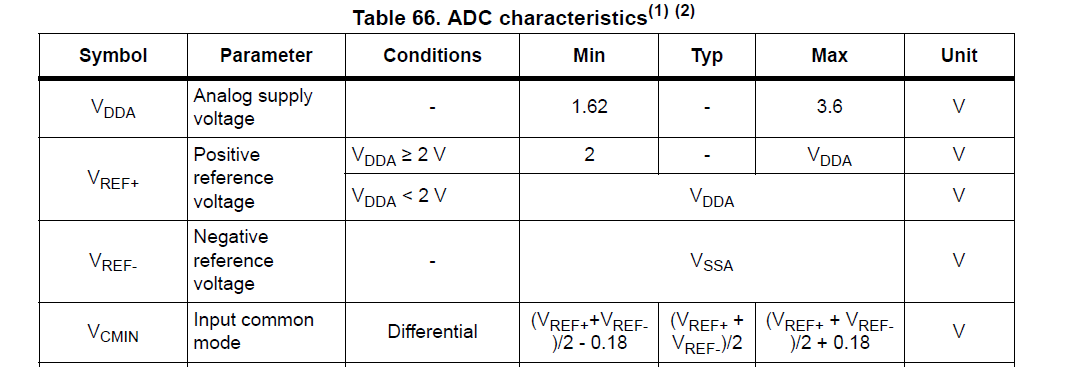

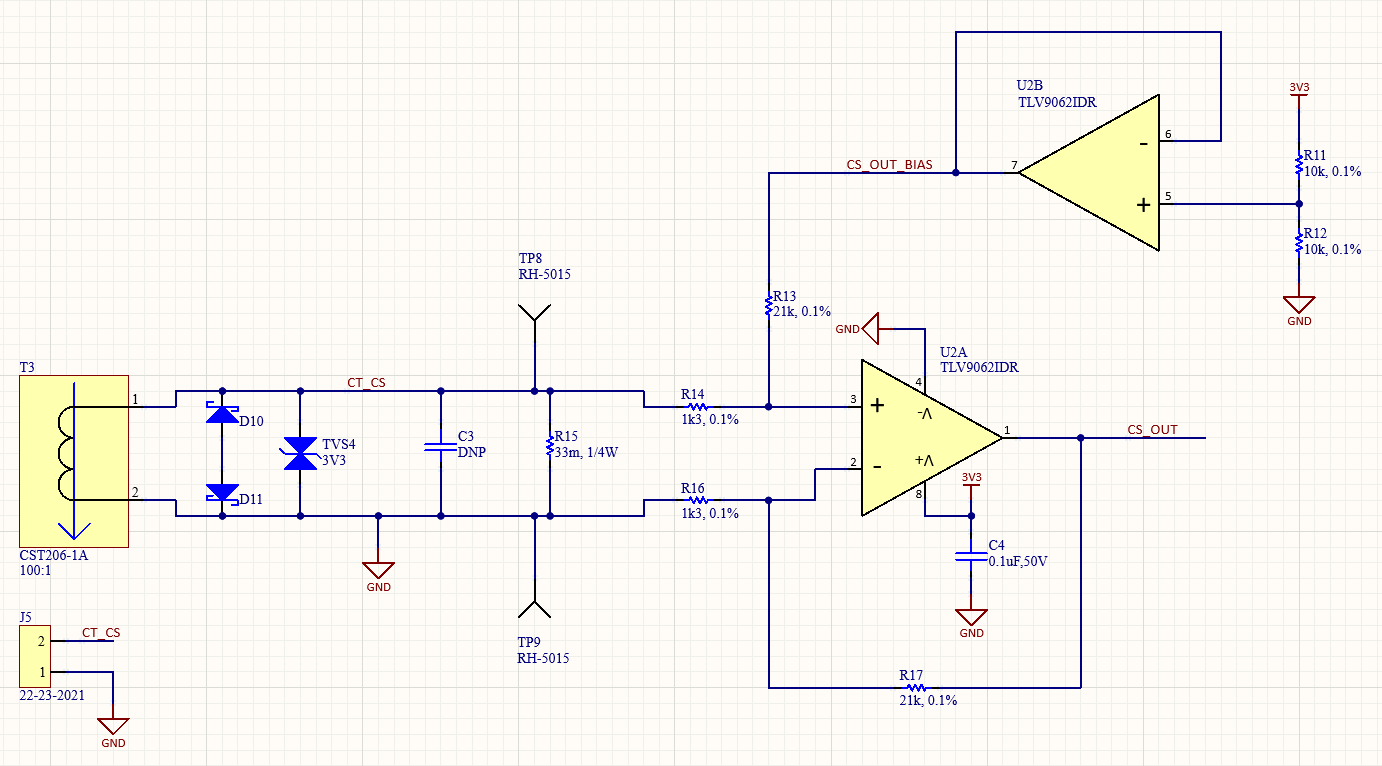

### Current Sense Schematic Parameters

Vrefp = Vcc;    % ADC positive reference, V
Vrefn = 0;      % ADC negative reference, V

% DC bias applied to output of current sense amplifier, V
Vbias = Vcc/2;

% Current sense CT burden resistor, Ohm
R15 = 33e-3;    
R17 = 21e3;     % Ohm
R16 = 1.3e3;    % Ohm

G_cs = R17/R16;  %% Current sense amplifier gain, V/V

% Set the primary current to peak, with some margin for safety, A
I_p_max = INVERTER.OCP_limit*1.20;

% Max current of current sense CT, A
I_ct_max = I_p_max/CURR_FB.CT_ZCD_Ns;

### Operating single ADC channel in differential mode

#### NOTE: This is sub-optimal, explored out of curiousity

% Compute max burden resistance if current sense gain is fixed

% Input common mode range: min, typ., max.
V_cmin = [((Vrefp+Vrefn)/2)-0.18 ((Vrefp+Vrefn)/2) ((Vrefp+Vrefn)/2)+0.18];

% Min/Max voltage of current sense amplifier output, V
V_cs_max = (I_ct_max*R15)*G_cs + Vbias;
V_cs_min = (-I_ct_max*R15)*G_cs + Vbias;
V_cs =[V_cs_min V_cs_max];

% ADC non-inverting input, V
Vadc_inp = V_cs;
% ADC inverting input, V
Vadc_inn = Vbias;

V_cm = (Vadc_inp + Vadc_inn)/2;


% Ensure that the input common mode rating of ADC is not violated
for vcm=V_cm
    if vcm <= V_cmin(1)
        error("ADC Input common mode rating (V_CMIN) violated: %0.4f =< %0.4f V", vcm, V_cmin(1));
    end
    if vcm >= V_cmin(3)
        error("ADC Input common mode rating (V_CMIN) violated: %0.4f >= %0.4f V", vcm, V_cmin(3));
    end
end

### Operating two ADC channels in single-ended mode

## Print Results


fprintf("\n\n################ Current Sense/Feedback BEGIN ##########################\n\n")
fprintf("Max ZCD CT Burden Resistor: %0.2f Ohm\n\n",CURR_FB.R_zcd_burden_max);
fprintf("################ Current Sense/Feedback END ##########################\n\n")
